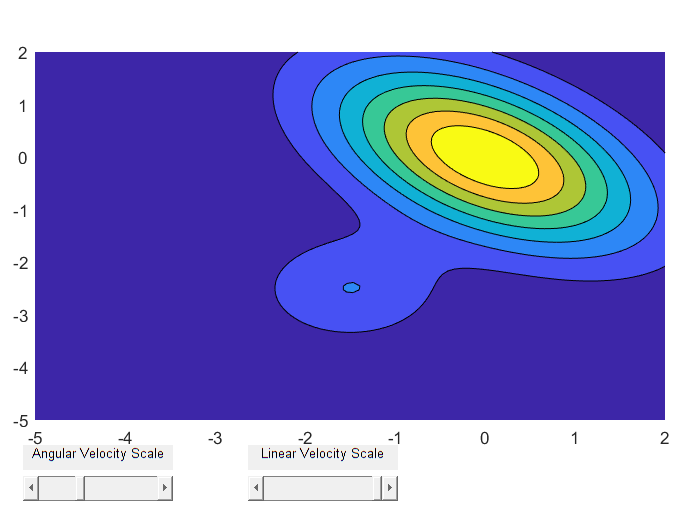

clc; clear; 

%establishing mountain equation 
syms x y
z = 16*exp(-(x^2)/2 - (y^2)/2 - (x*y)/2) + 4*exp(-(x+1.5)^2 - (y+2.5)^2); 
[a,b] = meshgrid(linspace(-5,2,100));
graph = 16*exp(-(a.^2)/2 - (b.^2)/2 - (a.*b)/2) + 4*exp(-(a+1.5).^2 - (b+2.5).^2); hold on;

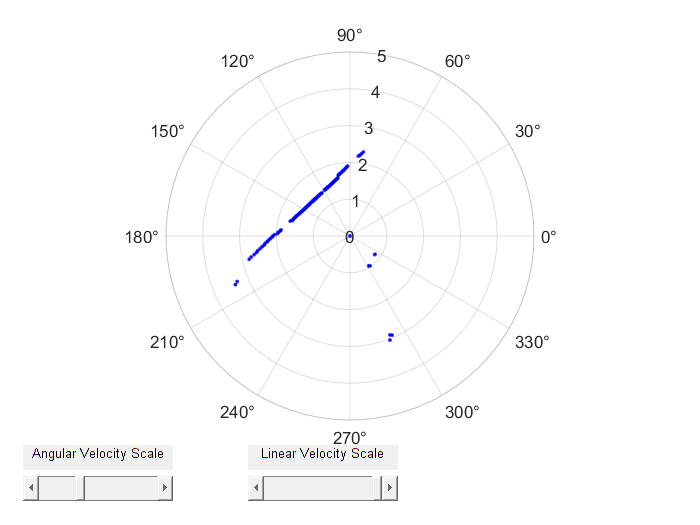


%[sensors,vels] = neatoSim(-2, 0, pi/2,1); %opening Neato simulation 
[sensors,vels]=neato('192.168.16.73'); %connecting to Neato 

%defining parameters 
lambda = 0.1; %step size 
grad = gradient(z, [x,y]); %finding gradient of function 
position = [-2;0]; %starting position 
head = [0;1]; %Neato starts by pointing in the +y direction 
n = 0; 
n_max = 12; 
R = zeros(n_max,2); %matrix to store position values 
R(1,1) = -2; R(1,2) = 0; %populating with starting position 
Rcount = 1; 
tolerance = 0.1;
grad_i = double(subs(grad, {x, y}, {position(1), position(2)})); %gradient of starting position 

%defining speed parameters 
linear_speed = 0.1; 
angular_speed = 0.15;

%populating position matix and sending commands to the Neato 
while n < n_max && norm(grad_i) > tolerance

    %calculating angle of turn  
    angle = cross([head;0], [grad_i;0]);  
    direction = sign(angle(3)); %finding the sign of angle 
    angle_of_turn = asin(norm(angle)/(norm(head)*norm(grad_i))); %finding the angle

    %using time as a constraint of turn 
    angle_time = double(angle_of_turn) / angular_speed;

    t_0 = clock; 
   
    while (etime(clock, t_0) < angle_time) 
        vels.lrWheelVelocitiesInMetersPerSecond = [-direction*angular_speed*0.245/2, direction*angular_speed*0.245/2];
    end 

    head = grad_i; %updating the position Neato is facing

    %calculating distance before next turn  
    distance = norm(grad_i*lambda);
    distance_time = distance / linear_speed;

    t_1 = clock; 

    while (etime(clock, t_1) < distance_time)
        vels.lrWheelVelocitiesInMetersPerSecond = [linear_speed, linear_speed];
        pause(0.00001); 
    end 

    vels.lrWheelVelocitiesInMetersPerSecond = [0,0]; %stopping wheels 

    %updating all values 
    position = position + lambda * grad_i; %update position for graphing 

    R(Rcount+1,1) = position(1,1); %populating position values to matrix R for graphing  
    R(Rcount+1, 2) = position(2,1);
    Rcount = Rcount + 1; 

    grad_i = double(subs(grad, {x, y}, {position(1), position(2)})); %update gradient value 
   
    n = n + 1;
end 


%ploting contour map and theoretical path to the top of the hill 
%{
contourf(a,b,graph,7); hold on;
plot(R(:,1),R(:,2),'-','Color','Red');
legend('Contour Map', 'Theoretical Path'); 
title('Contour Map');
xlabel('X position');
ylabel('Y position');
%}